# Feedback controller design for a Cascaded system (Tj - T)

# based  Ziegler Nichols with IMC method   

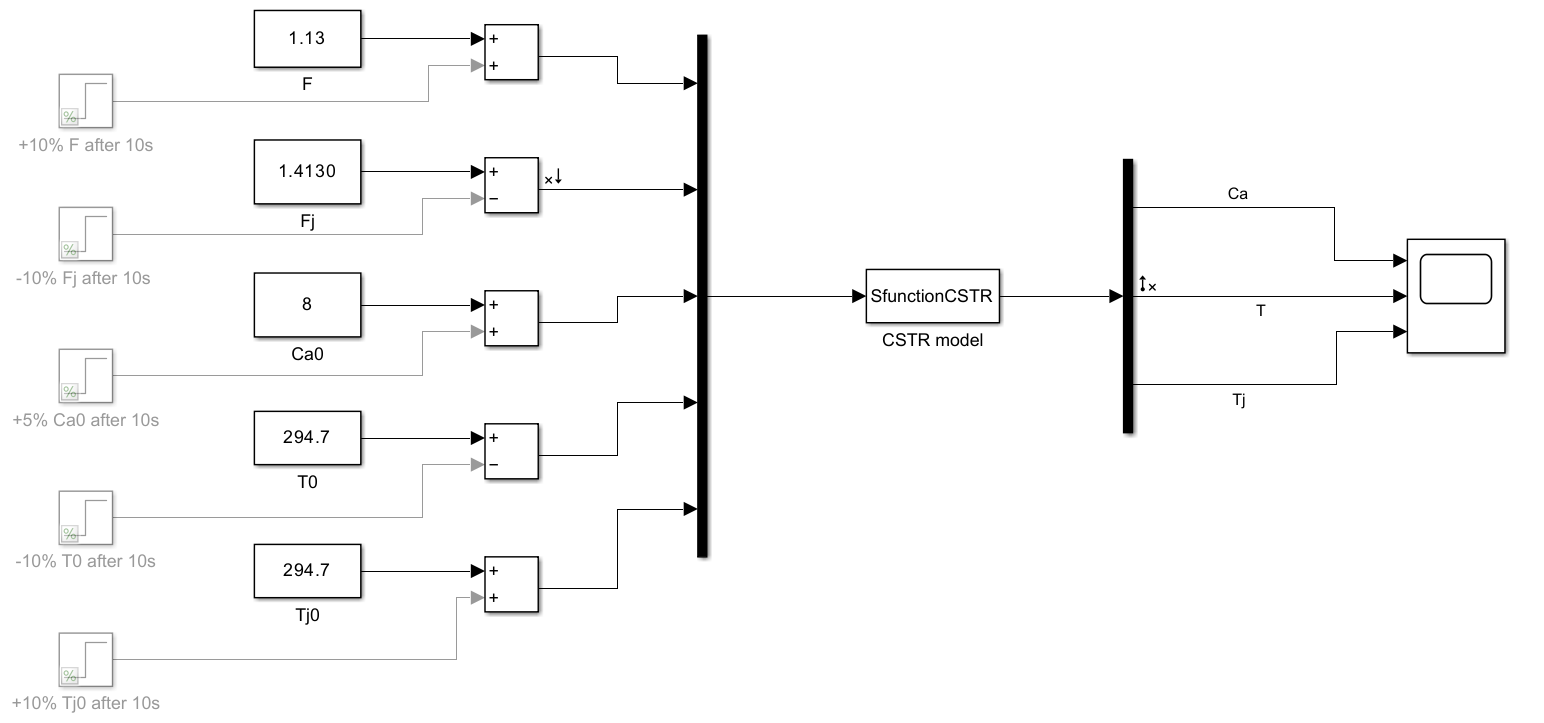

**Given ****: ** **A simulink nonlinear process model  ( CSTR Model)  **

## **Ziegler Nicols with IMC Method :**

**Ziegler Nichols method is based on  **the assumption that  the required input /output  model is ** a first order transfer  function with time delay  ( or dead time) ( See Lecture-6, Part-I, page 12  ) .**

First of all   one should obtain such a transfer function  (FOPTD- first order plus  time delay)  which approximates  the linear dynamic relationship between input and ouput of our interest.  In this case input is  Fj and output is T.

**Steps to follow :**

**1) Linearize the  system  by considering  the particular single input and single output  ** by using the   Model Linearizer tool. 

Obtain the linear state space model data  ( linsys1)  for this particular I/O pair.

Copy  **linsys1** data to the MATLAB Wokspace.

**2) I**t is possible to obtain a transfer function model G  in   "s" domain  based on  linearized system matrices (A,B,C,D)  and 

G0 ( steady state gain matrix) or  based on  state space data  obtained  by the Model  linearizer ( e.g. linsys1) **. **

The Matlab built in function is **tf** . We can use  it as follows : 

Gplant2 = tf(linsys3)

Gplant2 =
 
  From input "Tj Set point Temperature" to output "T":
            135.1 s + 6360
  -----------------------------------
  s^3 + 141.6 s^2 + 4170 s + 1.114e04
 
Name: Linearization at model initial condition
Continuous-time transfer function.
Model Properties


In this case  a third* order* transfer function  is generated.  

Approximate this  3rd order Gplant2 as  a ***first order*** transfer function with a **time delay, **Td,   since the  Ziegler- Nichols controller  tuning  method requires that.

**3)** Therefore we will follow another approach . First of all, we  plot the step response  curve for  the output  based on transfer function ,G :

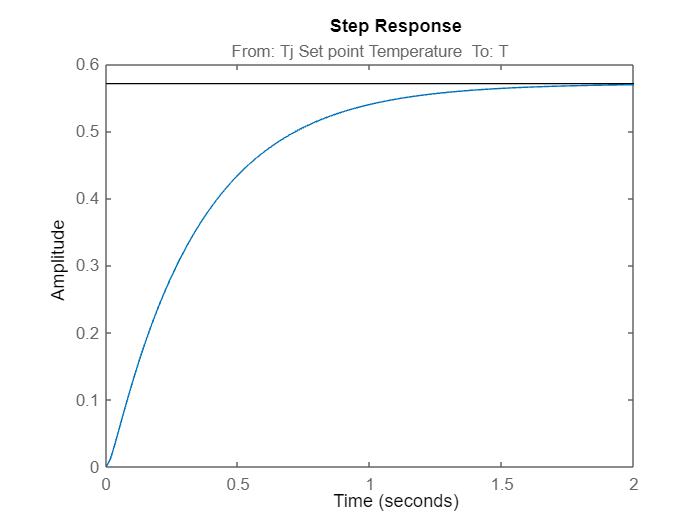

figure(1)
step(Gplant2)

Observe the output response  curve ; it has a slight S-shape. 

**4) **Store  the step response data   as output  variable , y  and time vector , t  . 

The following MATLAB commond  applies a unit step change  in the input and  gets the  output response, y, at each time point :

[y,t] = step(Gplant2);


Plot  the ouput response data  again :

figure(2)
plot(t,y,'k')
title('Process reaction curve')

**5) **Find  parameters** , gain (K), time constant (T)  and  dead time (Td) **which appear in the FOPDT transfer function model .

The following MATLAB script was adopted  from Ravikiran Yalamarthi, who published the his MATLAB  code  in June 2020  on the web pages  of MATLAB file exchange .

(See the hyperlink  :  [Process Reaction Curve](https://de.mathworks.com/matlabcentral/fileexchange/77371-process-reaction-curve)  )

Calculate the slope at each point :

slope = gradient(y,t)

slope =     0.6825
    0.9770
    1.3397
    1.4148
    1.4081
    1.3727
    1.3259
    1.2745
    1.2218
    1.1694


Find out  coordinates of the point of inflection :

[tslope,idx] = max(slope)

tslope = 1.4148

idx = 4

tIP = t(idx)

tIP = 0.0466

yIP = y(idx)

yIP = 0.0522

Estimate  the tangent  line  of the step response curve  at  the inflection point :

yTangentLine = tslope*(t-tIP) + yIP

yTangentLine =    -0.0137
    0.0083
    0.0303
    0.0522
    0.0742
    0.0962
    0.1182
    0.1402
    0.1622
    0.1842


Plot the  inflection point and  the tangent line on step response curve :

hold on
plot(tIP,yIP,'r*'),grid on 
plot(t,yTangentLine,'b')
ylim([0 1])            % zoom-in  in the previous plot 
xlabel( 'time (min)')
ylabel( 'y  ')

Estimate  parameters of the transfer function model (as a first order plus  dead time  -FOPTD model )

Timde delay (Dead time) , Td :

Td = tIP-(yIP/tslope)

Td = 0.0097

 Time constant , Tau : 

Tau1 = y(end)/tslope

Tau1 = 0.4021

Process gain, K :

K = y(end)/1

K = 0.5690

Show the delay time in plot

plot(Td,0,'g.','MarkerSize',15)

Define Approximate transfer function and plot the step response

G1new = tf(K,[Tau1 1],'InputDelay',Td)

G1new =
 
                       0.569
  exp(-0.00969*s) * ------------
                    0.4021 s + 1
 
Continuous-time transfer function.
Model Properties


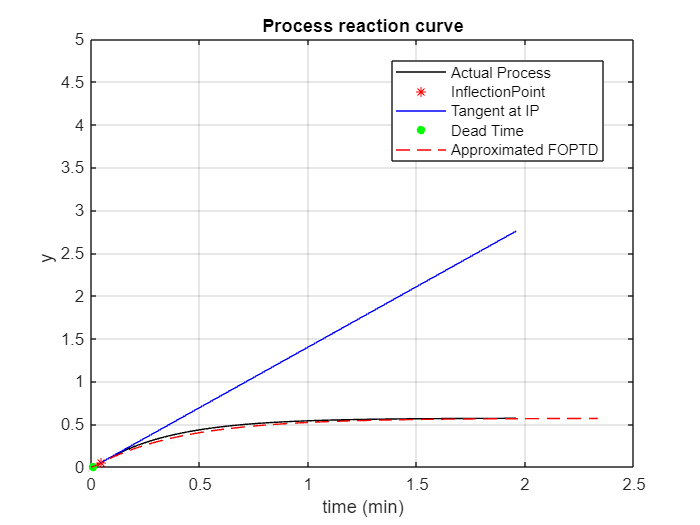

[z,t] = step(G1new);
plot(t,z,'r--'), hold off
legend('Actual Process','InflectionPoint','Tangent at IP','Dead Time', ...
    'Approximated FOPTD','Location','best')

xlim([0.000 2.5])
ylim([0.00 5])

**6)  Calculate the PI  conroller parameters :**

Based on the first order  transfer function  parameters , K, T,  (Td)   use  the IMC method (Bequette Table 7-2 )for Kp,TI calculation:

**PI  conroller parameters**** :  Kp **and** TI   **

Get the process gain as original reverse action

K = K

K = 0.5690

Tc = Tau1/3

Tc = 0.1340

Kp2 = (Tau1+Td/2)/(K*Tc)

Kp2 = 5.3363

TI2 = Tau1+Td/2

TI2 = 0.4070

KI2 = 1/TI2

KI2 = 2.4571